defaultDir = 'M:\Bergles Lab Data\Papers\P2ry1'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd(['Figure 1 - ISCs']);

%parameters for analysis
pulse = -100; %test pulse in pA for resistance measurement
pulseTime = [0 0.01 0.2 0.26]; %periods to measure resistance [baseline_start baseline_end ss_start ss_end]
peakProminenceThr = 25; %threshold in pA
conditions = {'Baseline','Furosemide'};
conditionTimes = [0 300; 540 840];

%%dir 
dname = '.\Data\WT_Furosemide';
folderlist = dir(dname);
folderlist = folderlist(3:end);
 dname = '.\Data\WT_Furosemide_MRS';
 temp = dir(dname);
 folderlist = [folderlist ; temp(3:end)];
 analyze = [0 0 1 0];

if exist('cell') | exist('cellS') 
   clear 'cell' 'cellS'; 
end

for i = 1:size(folderlist,1)
    if analyze(1)
        fileList = loadFileList([dname '\' folderlist(i).name '\*_p.abf']);
        [d,time] = loadPclampData(fileList{1});
        cellS(i).bl_R = calcRm(d,time,pulse,pulseTime);
    end
    
    if analyze(2)
        fileList = loadFileList([dname '\' folderlist(i).name '\*_gfi.abf']);
        [d,time,SR] = loadPclampData(fileList{1});
        out = msbackadj(time, d, 'WindowSize', 60,'StepSize',60);
        cellS(i).Vm = mean(d - out);
        %%figure for assessing basleine
        % figure; plot(time,d);
        %hold on; plot(time,out);
       % plot(time,d-out);
    end
    
    if analyze(3) %change in inward current
        fileList = loadFileList([folderlist(i).folder '\' folderlist(i).name '\*_gfv.abf']);
            if ~isempty(fileList)
            [d,time,SR] = loadPclampData(fileList{1});
            out = msbackadj(time, -d, 'WindowSize', 60,'StepSize',30);
            out = lowpass(out,5,5000);
            %figure for assessing basleine
            % figure; plot(time,out);
    %         hold on;
    %         plot(time,d-out);
            [pks,locs] = findpeaks(out,time,'MinPeakProminence', peakProminenceThr);
            %uncomment for peaks graph
            %findpeaks(out,time,'MinPeakProminence', peakProminenceThr)
            cellS(i).rawLocPk = [locs pks];
            
            if exist('stats')
                clear 'stats'; 
            end
            for j = 1:size(conditionTimes,1)
                stats(j).condition = conditions{j};
                stats(j).numPeaks = size(pks(locs > conditionTimes(j,1) & locs < conditionTimes(j,2)),1);
                stats(j).meanAmp = mean(pks(locs > conditionTimes(j,1) & locs < conditionTimes(j,2)),1);
                cumFunc = cumtrapz(time(time > conditionTimes(j,1) & time < conditionTimes(j,2)), ... 
                                         out(time > conditionTimes(j,1) & time < conditionTimes(j,2)));
                stats(j).integral = cumFunc(end);
                
            end
            
            cellS(i).stats = stats;
        end
    end
   
    if analyze(4)
        fileList = loadFileList([dname '\' folderlist(i).name '\*_pp.abf']);
        if ~isempty(fileList)
            [d,time] = loadPclampData(fileList{1});
            cellS(i).post_R = calcRm(d,time,pulse,pulseTime);
        end
    end
    
    
end

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\WT_Furosemide\180907_Cell1\18907003_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1508.2 s ~ 25 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 58 MB
opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\WT_Furosemide\180920_Cell1\18920003_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1502.5 s ~ 25 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 57 MB
opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\WT_Furosemide_MRS\180920_Cell2\18920014_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 2400.0 s ~ 40 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 92 MB


pkstatBlock = [];
ampstatBlock = [];
intstatBlock = [];

for i = 1:size(cellS,2)
    pkstatBlock(i,:) = [cellS(i).stats.numPeaks]/5;
    ampstatBlock(i,:) = [cellS(i).stats.meanAmp];
    intstatBlock(i,:) = [cellS(i).stats.integral]/300;
end

dim = [1.6 1.6];
compare2P(pkstatBlock(:,1),pkstatBlock(:,2),conditions,'Events Per Minute',dim,[5 12]);

    0.0689



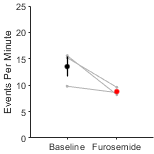

ylim([0 25]);
yticks(0:5:25);
export_fig('.\EPS Panels\furfreq.eps');


compare2P(ampstatBlock(:,1),ampstatBlock(:,2),conditions,'Mean Amp (pA)',dim,[5 12]);

    0.0076



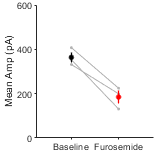

ylim([0 600]);
yticks(0:200:600);
export_fig('.\EPS Panels\furamp.eps');


compare2P(intstatBlock(:,1),intstatBlock(:,2),conditions,'Charge Transfer (-pA*s)',dim,[5 12]);

   1.7328e-04



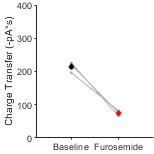

ylim([0 400]);
yticks(0:100:400);
export_fig('.\EPS Panels\furint.eps');

%%furosemide + MRS plot
list = loadFileList(['.\Data\WT_Furosemide_MRS\*\*_gfv.abf']);

if ~isempty(list)
    file = list{1};
    [d,time,SR] = loadPclampData(file);
    figure;
    plot(time,d,'Color', 'k');
    line([420 420+16*60],[175 175],'Color','k');
    line([15*60 15*60+8*60],[195 195],'Color','k');
    ylim([-1100 250])
end

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\WT_Furosemide_MRS\180920_Cell2\18920014_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 2400.0 s ~ 40 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 92 MB


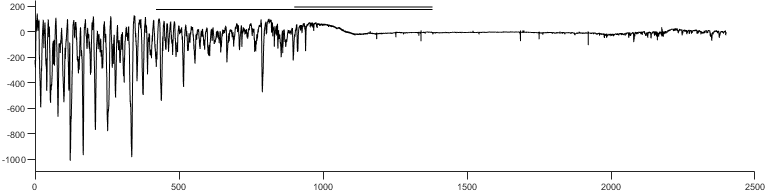

figQuality(gcf,gca,[8 2]);
export_fig('.\EPS Panels\Furosemide_MRS.eps');

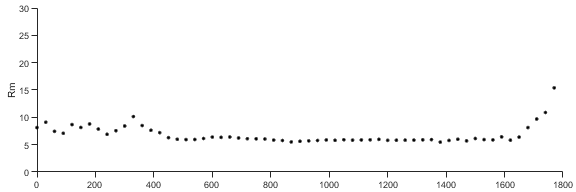

%%MRS + Rin steps
%list = loadFileList(['.\Data\WT_Furosemide_MRS\WT_MRS_Rin\*.abf']);
list = loadFileList(['D:\180925\18925021.abf']);

% if ~isempty(list)
%     file = list{1};
%     [d,si,h] = abfload(file);
%     d_work = d(:);
%     time = [0:1:size(d_work,1)-1]*si*10^-6;
%     figure;
%     plot(time,d_work(:),'Color', 'k');
%     figQuality(gcf,gca,[6 2]);
%     export_fig('.\EPS Panels\WT_MRS_pulse_Izero.eps');
% end

readings = struct([]);
for i = 1:size(d,3)
    temp = squeeze(d(:,:,i));
    time = [0:1:size(d,1)-1]*si*10^-6;
    readings(i).baseline = mean(temp(time > 0.5 & time < 0.55));
    readings(i).pulse = mean(temp(time > 0.65 & time < 0.70));
    readings(i).postpulse = mean(temp(time > 0.8 & time < 0.85));
    readings(i).avgBline = mean([readings(i).baseline readings(i).postpulse]);
    %readings(i).Rm = 5 * 10^-3/((readings(i).pulse - readings(i).avgBline)*10^-12)*10^-6; %%VC
    readings(i).Rm = ((readings(i).pulse - readings(i).avgBline)*10^-3)/(-400*10^-12)*10^-6; %%IC
end

time = [0:1:size(readings,2)-1]*30;
plot(time,[readings.Rm],'.','Color','k');
ylim([0 30]);
ylabel('Rm');
figQuality(gcf,gca,[6 2]);
    export_fig('.\EPS Panels\WT_MRS_pulse_Rm_Izero.eps');